# Lidar and Camera Calibration

This example shows you how to estimate a rigid transformation between a 3-D lidar sensor and a camera, then use the rigid transformation matrix to fuse the lidar and camera data.

## Overview

Lidar sensors and cameras are commonly used together in autonomous driving applications because a lidar sensor collects 3-D spatial information while a camera captures the appearance and texture of that space in 2-D images. You can fuse the data from these sensors to improve your object detection and classification. Lidar-camera calibration estimates a transformation matrix that gives the relative rotation and translation between the two sensors. You use this matrix when performing lidar-camera data fusion.

This diagram illustrates the workflow for the lidar and camera calibration (LCC) process, where we use checkerboard as a calibration object. We extract the checkerboard corners and planes from lidar and camera data, then establish a geometrical relationship between their coordinate systems to perform calibration. For more information on lidar-camera calibration process, see [What is Lidar Camera Calibration?](docid:lidar_ug#mw_7cf00201-70bf-4e99-864c-0798f09487b0)

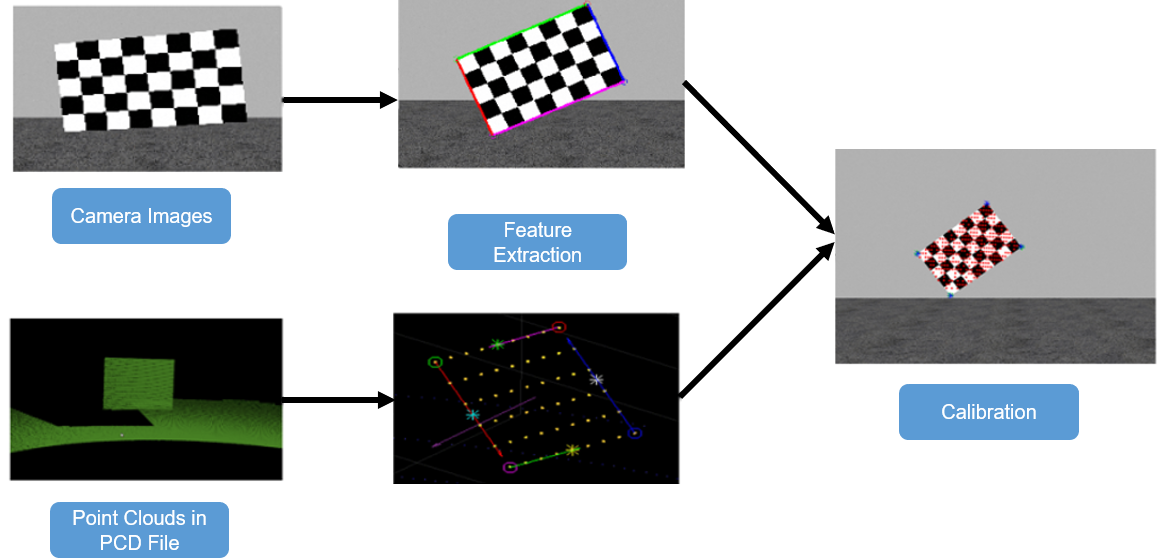

This example uses data from two different lidar sensors, a $	Velodyne LiDAR\textregistered $ HDL-64 sensor and a $	Velodyne LiDAR\textregistered $ VLP-16 sensor. For the HDL-64 sensor, use data collected from a Gazebo environment.

      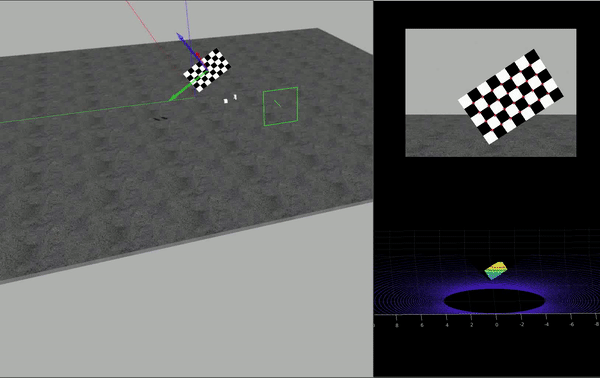

The HDL-64 sensor captures data as a set of PNG images and corresponding PCD point clouds. This example assumes that you already know the intrinsic parameters of the camera. For more information on extracting camera intrinsic parameters, see [Single Camera Calibration](docid:vision_ug#example-EvaluatingCameraCalibrationExample). 

## Load Data

Load the Velodyne HDL-64 sensor data from Gazebo.

clearvars; close all; clc;
camera = 'IRayCamera';

imagePath = fullfile('./', camera);
ptCloudPath = fullfile('./', 'VelodyneLidar_manual_pcd_cropped');
cameraParamsPath = fullfile('../camera_intrinsic/', strcat(camera, '.mat'));
res_path = fullfile('./', strcat('res_', camera, '.mat'));
json_path = fullfile('./', strcat('VelodyneLidar_to_', camera, '_extrinsic.json'));

% Square size of the checkerboard.
squareSize = 100;
padding = [20, 20, 20, 20];

% Load camera intrinsics.
intrinsic = load(cameraParamsPath);

% Load images using imageDatastore.
imds = imageDatastore(imagePath);
imageFileNames = imds.Files;

% Load point cloud files.
pcds = fileDatastore(ptCloudPath,'ReadFcn',@pcread);
ptCloudFileNames = pcds.Files;

% Set random seed to generate reproducible results.
rng('default')

## Detect Checkerboard Corners

This example uses a checkerboard pattern for calibration. First, estimate the checkerboard edges from the camera data. Use the [`estimateCheckerboardCorners3d`](docid:lidar_ref#mw_c97dba36-970a-49f5-a302-156a4d386ac4) function to calculate the coordinates of the checkerboard corners and size of the actual checkerboard in millimeters. The function estimates corners as 3-D coordinates in world coordinate system.

[imageCorners3d,checkerboardDimension,dataUsed] = ...
    estimateCheckerboardCorners3d(imageFileNames,intrinsic.cameraParams,squareSize, 'Padding', padding, 'MinCornerMetric', 0.4);


% Remove image files that are not used.
imageFileNames = imageFileNames(dataUsed);

Visualize the results by using the `helperShowImageCorners` helper function.

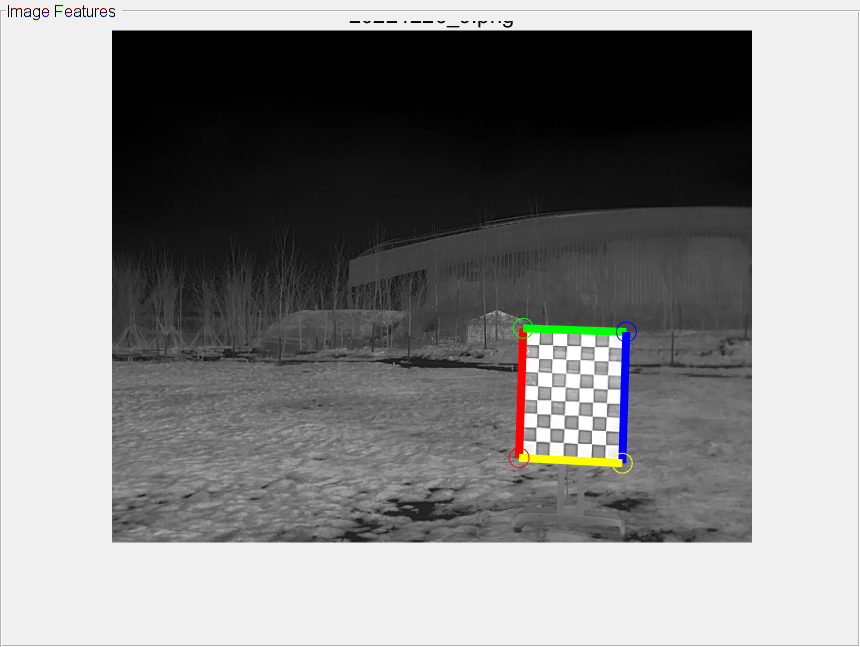

% Display checkerboard corners.
helperShowImageCorners(imageCorners3d,imageFileNames,intrinsic.cameraParams)

## Detect Checkerboard Plane 

Next, use the [`detectRectangularPlanePoints`](docid:lidar_ref#mw_ad9b338a-d55f-46f2-b603-f90f78137a4d) function to detect the checkerboard plane in the lidar data. The function detects the checkerboard using the board dimensions calculated by the [`estimateCheckerboardCorners3d`](docid:lidar_ref#mw_c97dba36-970a-49f5-a302-156a4d386ac4) function.

% Extract the checkerboard ROI from the detected checkerboard image corners.
% roi = helperComputeROI(imageCorners3d,5);

% Filter the point cloud files that are not used for detection.
ptCloudFileNames = ptCloudFileNames(dataUsed);
[lidarCheckerboardPlanes,framesUsed,indices] = ...
    detectRectangularPlanePoints(ptCloudFileNames,checkerboardDimension, MinDistance=1, DimensionTolerance=0.1);

% Remove ptCloud files that are not used.
ptCloudFileNames = ptCloudFileNames(framesUsed);

% Remove image files.
imageFileNames = imageFileNames(framesUsed);

% Remove 3-D corners from images.
imageCorners3d = imageCorners3d(:,:,framesUsed);

Visualize the detected checkerboard by using the `helperShowCheckerboardPlanes` function.

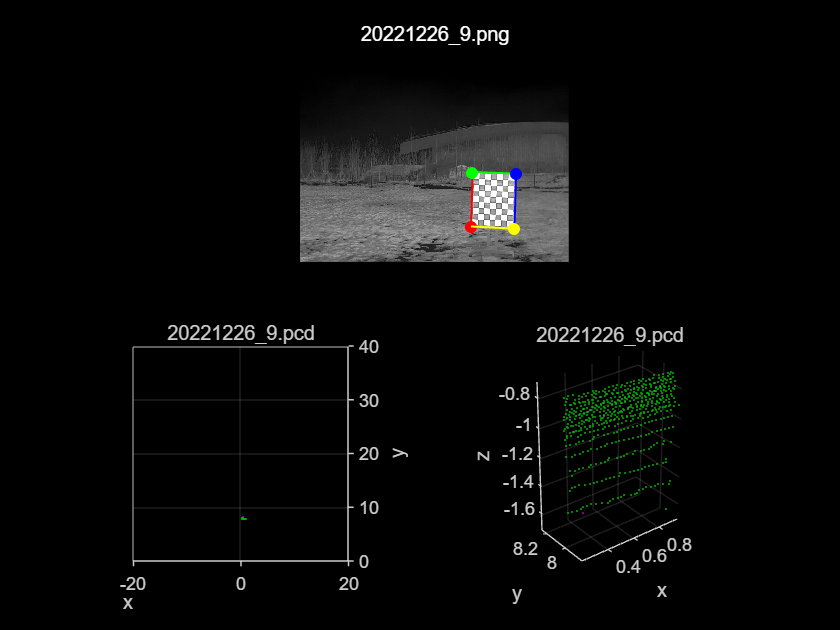

helperShowCheckerboardPlanes(ptCloudFileNames, indices, imageFileNames, imageCorners3d, intrinsic.cameraParams)

## Calibrate Lidar and Camera

Use the [`estimateLidarCameraTransform`](docid:lidar_ref#mw_57f25029-bfbd-4b17-b9a2-bafb8a122d50) function to estimate the rigid transformation matrix between the lidar sensor and the camera. 

[tform,errors] = estimateLidarCameraTransform(lidarCheckerboardPlanes, ...
    imageCorners3d,intrinsic.cameraParams);

After calibration, you can use this transformation matrix to:

- Project lidar point clouds on images, using the [`projectLidarPointsOnImage`](docid:lidar_ref#mw_95dcfa49-6a6d-4bbc-ae18-57ac95d7a537) function.

- Enhance lidar point clouds using color information from images, using the [`fuseCameraToLidar`](docid:lidar_ref#mw_113ffc27-3872-4795-a67c-edd3a144ac6a) function.

Use the `helperFuseLidarCamera` function to visualize the lidar and the image data fused together.

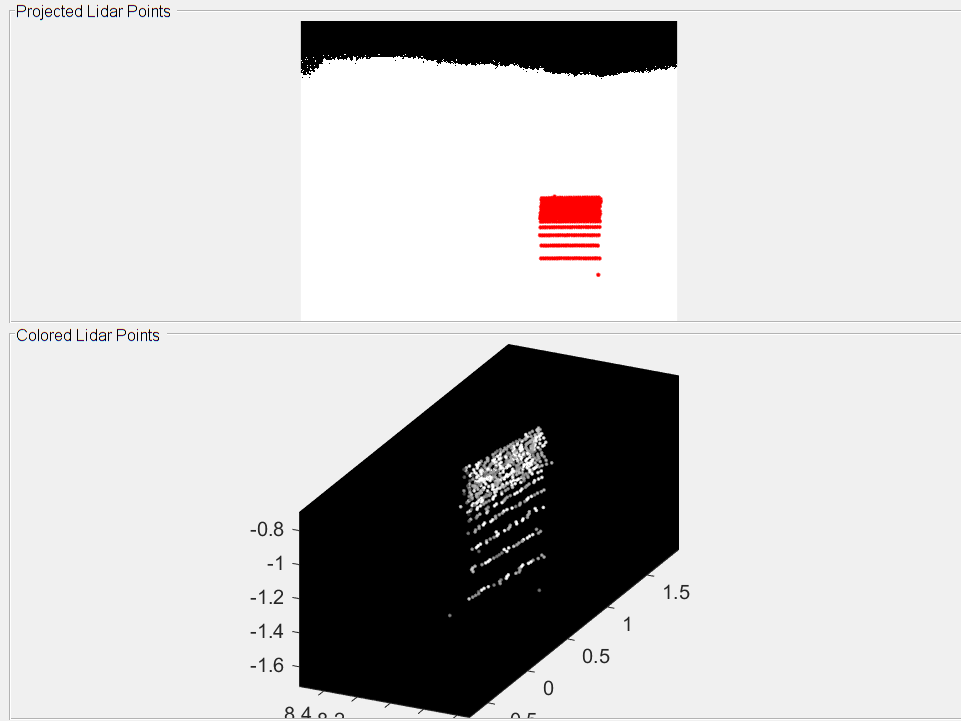

helperFuseLidarCamera(imageFileNames,ptCloudFileNames,indices, intrinsic.cameraParams,tform);

## Visualize Calibration Errors

You can estimate the calibration accuracy using these types of errors.

- Translation Error — The difference between the centroid coordinates of the checkerboard planes in the point clouds and those in the corresponding images, in meters. 

- Rotation Error — The difference between the normal angles defined by the checkerboard planes in the point clouds and those in the corresponding images, in radians.

- Reprojection Error — The difference between the projected (transformed) centroid coordinates of the checkerboard planes from the point clouds and those in the corresponding images, in pixels.

Plot the estimated error values by using the `helperShowError` function.

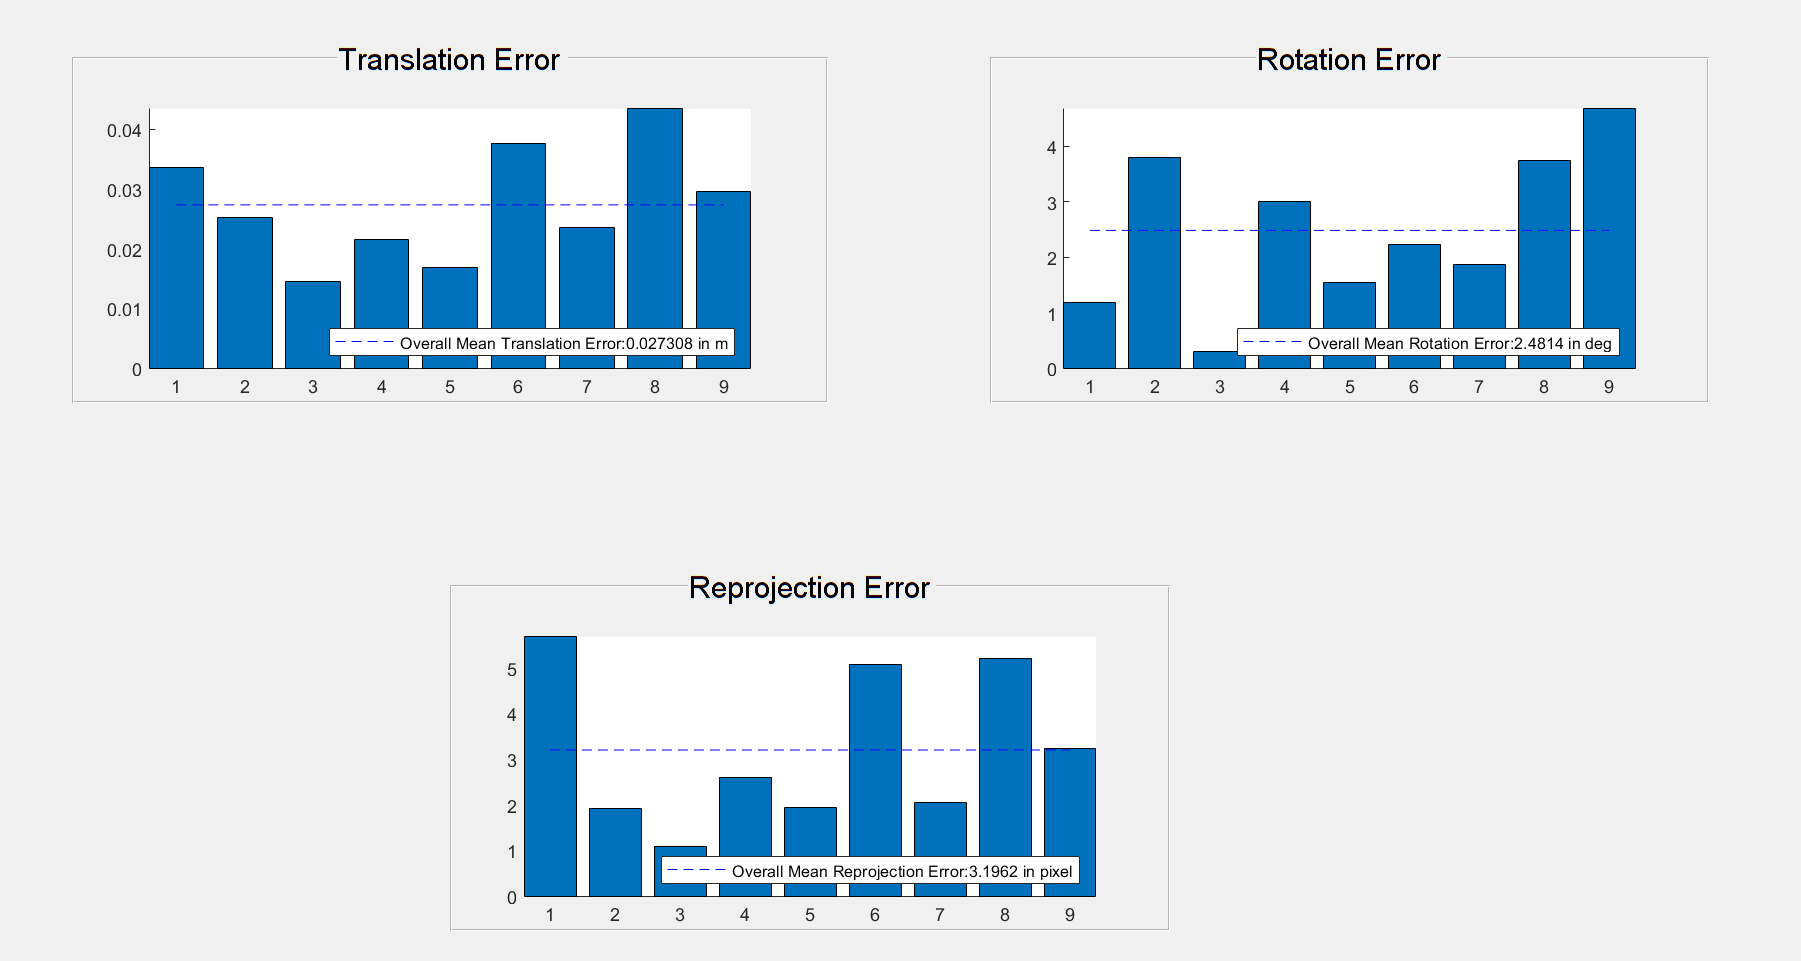

helperShowError(errors)

## Save results

save(res_path, 'tform', 'errors');

% save .json
addpath('../../3rdpart/jsonlab');

output = struct();
output.R = tform.R;
output.T = tform.Translation;
output.RT = tform.A;
savejson('', output, json_path);

## Summary

This example provides an overview of the lidar-camera calibration workflow and shows you how to use a rigid transformation matrix to fuse lidar and camera data.

## References

[1] Zhou, Lipu, Zimo Li, and Michael Kaess. “Automatic Extrinsic Calibration of a Camera and a 3D LiDAR Using Line and Plane Correspondences.” In 2018 IEEE/RSJ International Conference on Intelligent Robots and Systems (IROS), 5562–69. Madrid: IEEE, 2018. https://doi.org/10.1109/IROS.2018.8593660.

[2] Arun, K. S., T. S. Huang, and S. D. Blostein. “Least-Squares Fitting of Two 3-D Point Sets.” IEEE Transactions on Pattern Analysis and Machine Intelligence PAMI-9, no. 5 (September 1987): 698–700. https://doi.org/10.1109/TPAMI.1987.4767965.

*Copyright 2019 The MathWorks, Inc.*